## Description

This is main routine of FEM code for 2D linear elasticity, The architecture of this program is developed by Li, B. 2010 April, other work is contributed by Qiu, JS. 2023 April.

In this program, we will deal with 2D plane stress problem of trapezoidal domain.

## Set Parameters of Mesh and Units

Here we set parameters of mesh. We have two types of elements: 

- triangular element with 3 nodes

- quadrilateral element with 4 nodes

We will use structured mesh to divide the material domain, thus we need to seed edges of x and y direction.

clear

flag     = 1; % 1: triangular element;   2: quadrilateral element.
x_seed_e = 1; % seed number of element in x direction
y_seed_e = 1; % seed number of element in y direction

For finite element analysis (**FEA**), it is necessary to determinate the consistent unit system at the very beginning. In the following analysis, we will choose **SI** unit system:

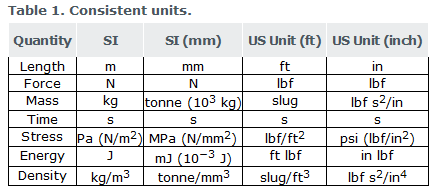

## 1. Mesh Generation

In this section we obtain mesh information: nodal index with coordinates `X_a, `element index and corresponding global nodal index `elem`. The data structure of output data is:


$$X_a=\left(\begin{array}{cc}
x^{(1)} & y^{(1)} \\
x^{(2)} & y^{(2)} \\
\vdots & \vdots \\
x^{(N)} & y^{(N)}
\end{array}\right)_{N\times2}, 
\quad 
elem=\left(\begin{array}{cccc}
I^{(1)} & J^{(1)} & \ldots & K^{(1)} \\
I^{(2)} & J^{(2)} & \ldots & K^{(2)} \\
\vdots & \vdots & \vdots & \vdots \\
I^{(M)} & J^{(M)} & \ldots & K^{(M)}
\end{array}\right)_{M\times NNE}$$


where `N` is the total number of nodes, `M` is the total number of elments. `NNE` denotes the nodal number of element, for triangular element, `NNE=3`; For quadrilateral element, `NNE=4`.

We use variable `node_id` to keep geometric information for structured 2D mesh (i.e. nodes on the edges). `node_id` is a `[x_seed_n,y_seed_n]` matrix, where `x_seed_n,y_seed_n` are seed number of x,y axis. `node_id` stores geometry distribution of nodal points, thus it is very convenient to get node index of one edge.

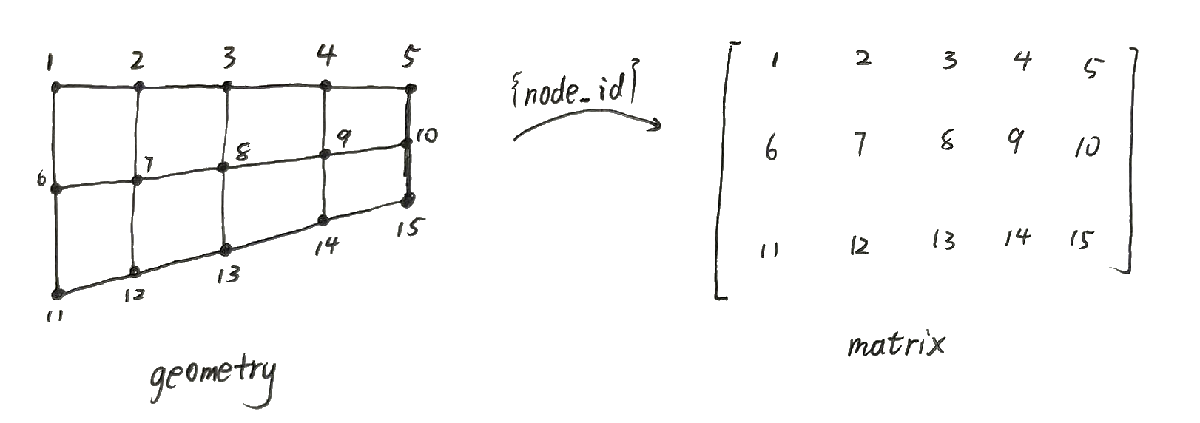

We follow Abaqus™ standard of local node ordering in elements, the elements connectivities are all ordered in a counter-clockwise fashion.

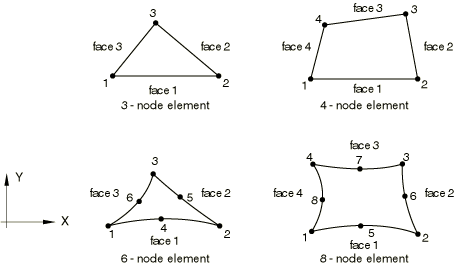

*(from Abaqus documentation: Two-dimensional solid element library)*

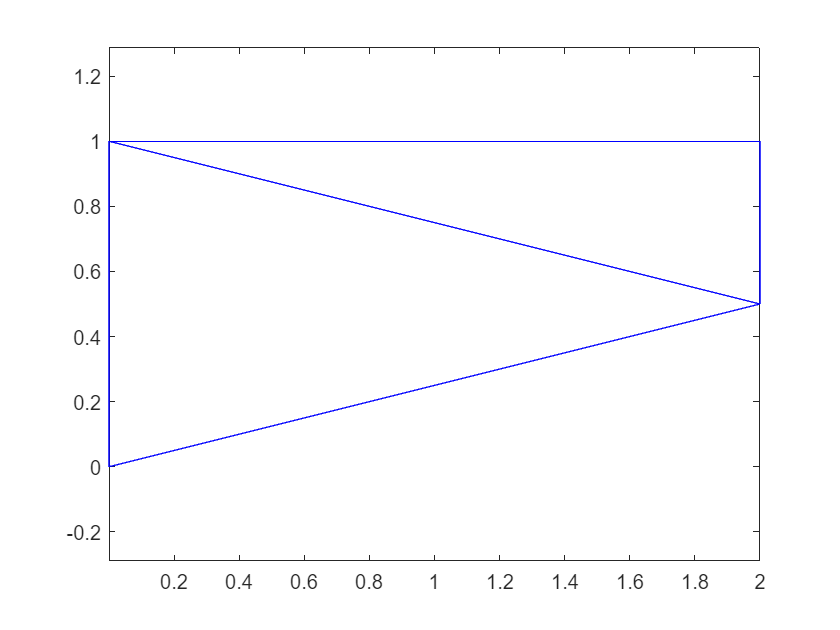

% define domain for trapezoidal
ledge = [0    1]; % [m]
redge = [0.5    1]; % [m]
height= [0   2]; % [m]

% generate mesh
[X_a,elem,node_id]=generate_mesh(flag, x_seed_e, y_seed_e, ledge, redge, height);
    
% Check the initial mesh
if flag == 1
  triplot(elem,X_a(:,1),X_a(:,2));
  axis equal
  % plot_node_number(node_id,X_a)
  % plot_elem_number(X_a,elem)
  str_fig_name = strcat('./figs/mesh_',num2str(x_seed_e),'_',num2str(y_seed_e),'_tri.png');
  saveas(gcf,str_fig_name)
elseif flag == 2
  quadplot(elem,X_a(:,1),X_a(:,2));
  axis equal
  % plot_node_number(node_id,X_a)
  % plot_elem_number(X_a,elem)
  str_fig_name = strcat('./figs/mesh_',num2str(x_seed_e),'_',num2str(y_seed_e),'_qua.png');
  saveas(gcf,str_fig_name)
end

To obtain area and geometric center of element, we use MATLAB built-in functions `polyshape()` and `centroid()`. Note that centroid of quadrilateral element has different definitions (see [How can I construct the centroid of a quadrilateral?](https://math.stackexchange.com/questions/2484814/how-can-i-construct-the-centroid-of-a-quadrilateral)). 

[Xg,Area] = g_center(X_a,elem);

[nodes,dim] = size(X_a);
[elements,NNE] = size(elem);

## 2. Boundary Conditions

Here we generate auxiliaire data structure to enforce boundary conditions:

### `boundary`

a vector with `2N` entries, each element of the vector is a boolean flag for the nodal displacement in x or y direction

- `1` for constrained

- `0` for free 

e.g. `(1 1 0 0 1 0 ...)` means node 1 has displacement boundary conditions applied in x and y direction, but node 3 has x displacement b.c. 

### `disp`

a vector with `2N` entries, each element of the vector is the prescribed nodal displacement in x or y direction. For those free nodes, use `(0 0)`.

### `l_area`

a vector with `N` entries, each element of the vector is the surface area associated with a node. If the node is not subjected to traction boundary conditions, its surface area is zero.

For 2D plane problem, the boundary is 1D of unit [Length], thus the surface area actually equals to the boundary length.

### Displacements imposition with variable `disp_condition`

- 1st col: 1 for row constraint, 2 for column constraint

- 2nd col: row or column index of `node_id`

- 3rd col: 1 for displacement in x, 2 for y, and 3 for in both x and y direction

- 4th col: value of the prescribed displacement, for x,y direction are both constrained, prescribed displacement always equals to 0

e.g apply displacement boundary condition on the edge of the domain at column 1, u(x,y)=(0.0 10.0) 

### Forces imposition (area of the nodes) with variable `force_condition`

- 1st col: 1 for row constraint, 2 for column constraint

- 2nd col: row or column index of `node_id`

e.g apply traction boundary conditions to the edge of the domain at row 1

disp_condition(1,:) = [2 1 3 0];
force_condition(1,:)= [1 1]; 
[boundary,disp,l_area]=Boundary_conditions(X_a,elem,node_id,disp_condition,force_condition);

## 3. Isotropic Elastic Material Properties

E  = 30000000; % Young's modulus [Pa]
nu = 0.3; % Poisson ratio

properties(1) = E;
properties(2) = nu;

## Matrix Notations Used in FEA

Before we construct $\mathbf{B}$ or $\mathbf{K}$ matrix in FEA, we will introduce matrix notation used in our procedures. The symbol notation follows reference *Finite Element Procedures, K.J.Bathe. *

### 3-node triangular element

The matrix notation of element stiffness matrix $\mathbf{K}$ is:


$$    \mathbf{K}^e=\int_{\Omega} \mathbf{B}^T \mathbf{D} \mathbf{B}~\mathrm{d} \Omega$$


Note that the formation of $\mathbf{B}$ matrix depends on the order of nodal displacement vector $\hat{\mathbf{U}}$, which is defined as

## 4. B matrix

B is a cell structure where B(i) is the B matrix of element i

[B, N]=B_matrix(X_a,elem,Xg,Area,flag);

## 5. K matrix

K is a 2Nx2N matrix, N is the total number of nodes

[K]=K_matrix(B,elem,X_a,Area,properties);

## 6. Forces vector

F is a vector with 2N entries

Load = 2e4; % traction [N/m]
[F]=F_vector(X_a,Load,l_area);

## 7. Enforce Essential Boundary Condition

[F,K]=Enforce_BC(F,K,boundary,disp,X_a);

## 8. Solve the problem

[u]=K\F;

## 9. Compute the strain, stress and pressure from the displacement

[Es,Ss,P]=constitutive(B,properties,u,elem,dim);

## 10. Post-processor

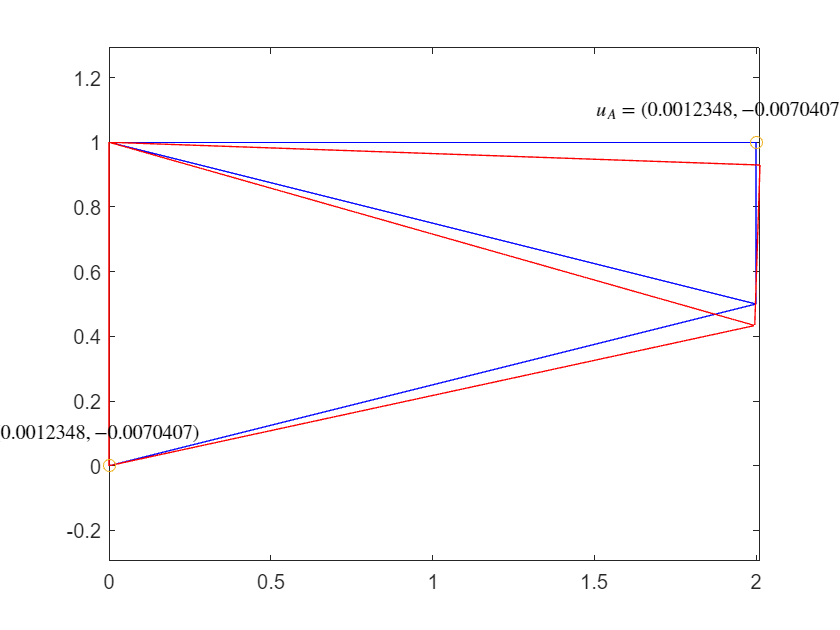

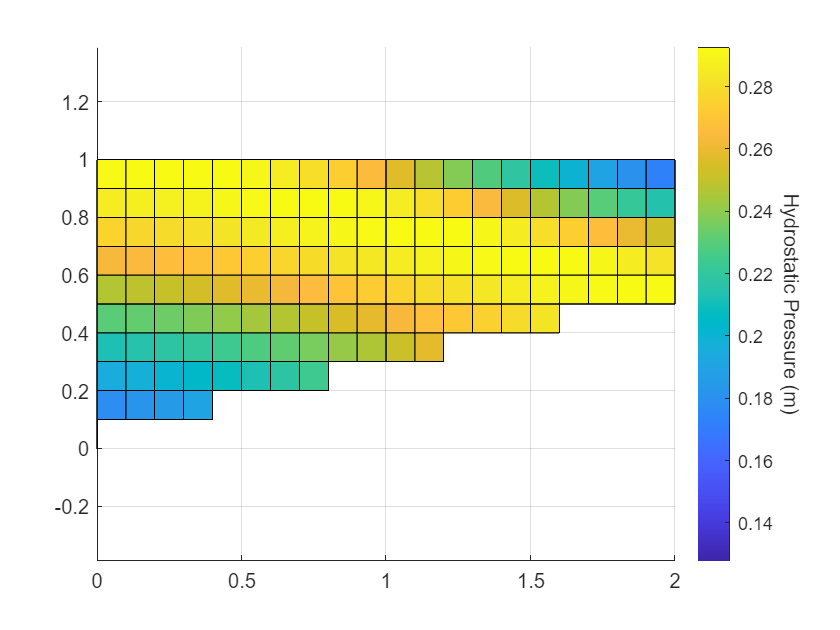

h=10; % amplification factor
plot_results(X_a,elem,P,u,h,N,flag,node_id,x_seed_e,y_seed_e);

save DATA Es Ss P u